# MSc Project IIS1 | BWFLnet_Water Analysis

#### Prepared by: Yuanfei Wang

#### Date: 17 July 2022

clc
clear
close all

### Model Setup and Initialisation

Initialisation of EPANET Matlab toolkit and loading of .net file.

epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
net_id = 'BWFLnet_MSc_2022_calibrated';
run( [epanet_path,'\start_toolkit'])

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet([net_id,'.inp']);

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "BWFLnet_MSc_2022_calibrated.inp"...
Input File "BWFLnet_MSc_2022_calibrated.inp" loaded sucessfuly.


load("wq_data.mat");
load("R_CData.mat");

### Network Data Loading

Load general network data, noting that this network has already been hydraulically calibrated, thus we can directly perform the quality analysis.

% Save element count variables
nn = net.NodeJunctionCount;
n0 = net.NodeReservoirCount;
np = net.LinkCount; % count of pipes and valves
D = net.getLinkDiameter';

% Save node and link index vectors
Reservoir_Idx = net.getNodeReservoirIndex;
Junction_Idx = net.getNodeJunctionIndex;
Link_Idx = double(net.getLinkIndex);

% Specify hydraulic and quality time steps (in seconds)
net.setTimeQualityStep(15*60); % 15 minute quality time steps
net.setTimeHydraulicStep(15*60); % 15 minute hydraulic time steps
nt = net.getTimeSimulationDuration./3600; % number of time steps in hours
days = 7; % simulation duration in days
net.setTimeSimulationDuration(nt*3600*days/7); % Set the simulation duration by changing days
nt = net.getTimeSimulationDuration./3600; % get the new nt

% Nodes name and chlorine concentrations
Junction_All_Name = {'BW9','BW7','BW1','BW2','BW3','BW4','BW5','BW6','BW12'};
Junction_SelectIdx = net.getNodeIndex(wq_data.node_ids([1,4,7,9]));
Junction_Name = Junction_All_Name([1,4,7,9]);
Junction_HydrantIdx = net.getNodeIndex(wq_data.node_ids([2,5,8]));
Junction_Hydrant_Name = Junction_All_Name([2,5,8]);
Junction_Reservoir_Name = Junction_All_Name([6,3]);
cext = wq_data.chlorine([6,3],:);
c_nodes_HydrantObs = wq_data.chlorine([2,5,8],:);
c_nodes_Obs = wq_data.chlorine([1,4,7,9],:);


% record mse data
mse_with1 = [0.0089, 0.0065, 0.0030, 0.0027;
    0.0275, 0.0230, 0.0179, 0.0164];
mse_with2 = [0.0099, 0.0069, 0.0029, 0.0030;
    0.0291, 0.0220, 0.0172, 0.0171];
mse_with3 = [0.0114, 0.0072, 0.0034, 0.0032;
    0.0311, 0.0227, 0.0171, 0.0160];
mse_without1 = [0.0050, 0.0021, 0.0017, 0.0017;
    0.0128, 0.0101, 0.0097, 0.0094];
mse_without2 = [0.0056, 0.0019, 0.0017, 0.0016;
    0.0128, 0.0097, 0.0092, 0.0097];
mse_without3 = [0.0061, 0.0023, 0.0021, 0.0021;
    0.0110, 0.0105, 0.0092, 0.0101];

mse_with_train = [mse_with1(1,:);mse_with2(1,:);mse_with3(1,:)];
mse_with_val = [mse_with1(2,:);mse_with2(2,:);mse_with3(2,:)];
mse_without_train = [mse_without1(1,:);mse_without2(1,:);mse_without3(1,:)];
mse_without_val = [mse_without1(2,:);mse_without2(2,:);mse_without3(2,:)];

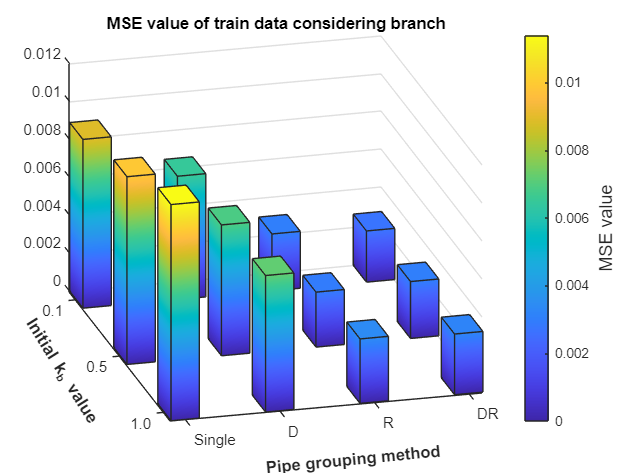

% Create boxplots
width = 0.3;
figure,
b1 = bar3(mse_with_train, width);
c1 = colorbar('eastoutside');
c1.Label.String = 'MSE value';
c1.Label.FontSize = 12;
for k = 1:length(b1)
    zdata = b1(k).ZData;
    b1(k).CData = zdata;
    b1(k).FaceColor = 'interp';
end
title('MSE value of train data considering branch');
set(gca,'xticklabel',{'Single','D','R','DR'});
set(gca,'yticklabel',{'0.1','0.5','1.0'});
set(gca,'XGrid','off','YGrid','off');
xlabel('Pipe grouping method','Rotation',5.5,'Position',[1.5,3.9,0],'FontWeight','bold');
ylabel('Initial k_b value','Rotation',-58,'Position',[0.2,3,0],'FontWeight','bold');
view(-15,20);

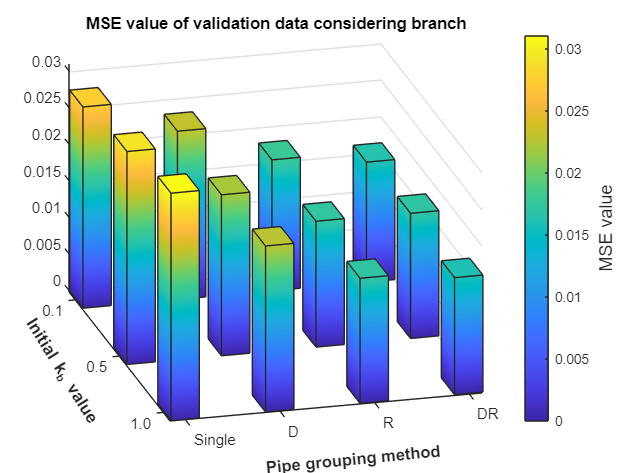

figure,
b2 = bar3(mse_with_val, width);
c2 = colorbar('eastoutside');
c2.Label.String = 'MSE value';
c2.Label.FontSize = 12;
for k = 1:length(b2)
    zdata = b2(k).ZData;
    b2(k).CData = zdata;
    b2(k).FaceColor = 'interp';
end
title('MSE value of validation data considering branch');
set(gca,'xticklabel',{'Single','D','R','DR'});
set(gca,'yticklabel',{'0.1','0.5','1.0'});
set(gca,'XGrid','off','YGrid','off');
xlabel('Pipe grouping method','Rotation',5.5,'Position',[1.5,3.9,0],'FontWeight','bold');
ylabel('Initial k_b value','Rotation',-58,'Position',[0.2,3,0],'FontWeight','bold');
view(-15,20);

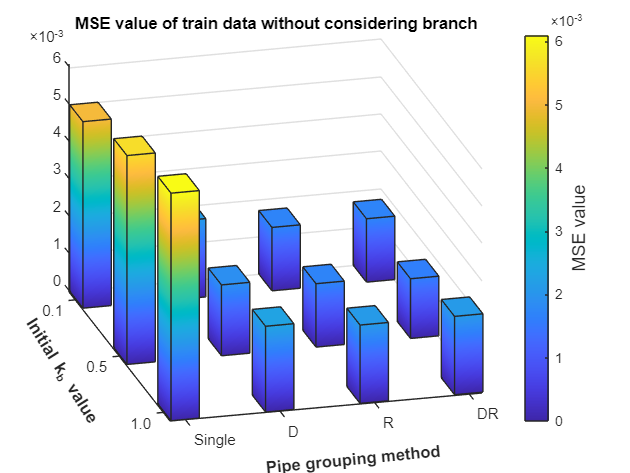

figure,
b3 = bar3(mse_without_train, width);
c3 = colorbar('eastoutside');
c3.Label.String = 'MSE value';
c3.Label.FontSize = 12;
for k = 1:length(b3)
    zdata = b3(k).ZData;
    b3(k).CData = zdata;
    b3(k).FaceColor = 'interp';
end
title('MSE value of train data without considering branch');
set(gca,'xticklabel',{'Single','D','R','DR'});
set(gca,'yticklabel',{'0.1','0.5','1.0'});
set(gca,'XGrid','off','YGrid','off');
xlabel('Pipe grouping method','Rotation',5.5,'Position',[1.5,3.9,0],'FontWeight','bold');
ylabel('Initial k_b value','Rotation',-58,'Position',[0.2,3,0],'FontWeight','bold');
view(-15,20);

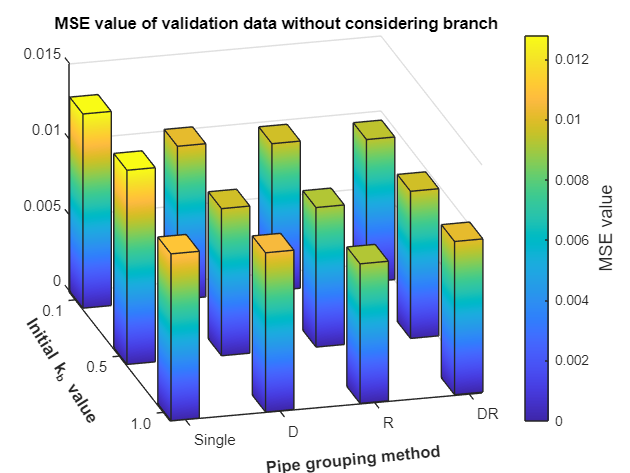

figure,
b4 = bar3(mse_without_val, width);
c4 = colorbar('eastoutside');
c4.Label.String = 'MSE value';
c4.Label.FontSize = 12;
for k = 1:length(b4)
    zdata = b4(k).ZData;
    b4(k).CData = zdata;
    b4(k).FaceColor = 'interp';
end
title('MSE value of validation data without considering branch');
set(gca,'xticklabel',{'Single','D','R','DR'});
set(gca,'yticklabel',{'0.1','0.5','1.0'});
set(gca,'XGrid','off','YGrid','off');
xlabel('Pipe grouping method','Rotation',5.5,'Position',[1.5,3.9,0],'FontWeight','bold');
ylabel('Initial k_b value','Rotation',-58,'Position',[0.2,3,0],'FontWeight','bold');
view(-15,20);

### Chlorine Simulation

Setup general chemical simulation parameters.

% Initialise EPANET simulation type
net.setQualityType('Chemical','mg/L');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero

% % Link bulk reaction coefficients
% lambda = 0.5*ones(np,1); % units of days^-1
% net.setLinkBulkReactionCoeff(1:np, -lambda);
% net.setOptionsPipeBulkReactionOrder(1);

% Initial concentrations at nodes (mg/L)
c0 = zeros(nn+n0,nt);
net.setNodeInitialQuality(net.NodeIndex,c0);
base_cext = ones(n0,1); 
pattern_cext = cext./(base_cext*ones(1,size(cext,2))); % extend vector over nt columns 

% For loop to assign new patterns to source contrations at reservoirs and
% source type
for i=1:n0
    patternId = sprintf('Res_C_%d',i);
    net.addPattern(patternId,pattern_cext(i,:));
    net.setNodeSourcePatternIndex(net.NodeReservoirIndex(i),net.getPatternIndex(patternId));
    net.setNodeSourceQuality(net.NodeReservoirIndex(i),base_cext(i));
    net.setNodeSourceType(net.NodeReservoirIndex(i),'CONCEN');  
end


### Results from EPANET Simulation

Simulate hydraulic and quality analyses using EPANET's solvers.

hydraulic_res = net.getComputedHydraulicTimeSeries;
quality_res = net.getComputedQualityTimeSeries;

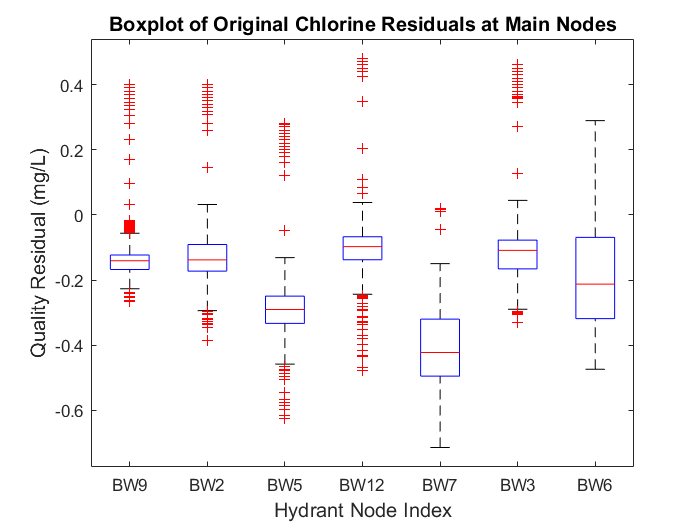


% Assign hydraulic results to network elements
h = hydraulic_res.Head(1:1+4*nt,1:nn).';
q = 1e-3*hydraulic_res.Flow(1:1+4*nt,:).';

% Assign quality results to network elements
c_nodes = quality_res.NodeQuality';
c_pipes = quality_res.LinkQuality';

% Get the simulated and observed data
c_nodes_Sim = c_nodes(Junction_SelectIdx,:);
c_nodes_Sim = c_nodes_Sim(:,1:end-1);
c_nodes_HydrantSim = c_nodes(Junction_HydrantIdx,:);
c_nodes_HydrantSim = c_nodes_HydrantSim(:,1:end-1);
c_nodes_Reservoir = pattern_cext;

% split the data
Sim_train = c_nodes_Sim(:,2*96+1:3*96);
Sim_val = c_nodes_Sim(:,3*96+1:end);
Sim_Hydrant_train = c_nodes_HydrantSim(:,2*96+1:3*96);
Sim_Hydrant_val = c_nodes_HydrantSim(:,3*96+1:end);

Obs_train = c_nodes_Obs(:,2*96+1:3*96);
Obs_val = c_nodes_Obs(:,3*96+1:end);
Obs_Hydrant_train = c_nodes_HydrantObs(:,2*96+1:3*96);
Obs_Hydrant_val = c_nodes_HydrantObs(:,3*96+1:end);

% Combine the two data sets
Junction_CombinedIdx = [Junction_SelectIdx,Junction_HydrantIdx];
Obs_Combined_train = [Obs_train; Obs_Hydrant_train];
Obs_Combined_val = [Obs_val; Obs_Hydrant_val];
Sim_Combined_train = [Sim_train; Sim_Hydrant_train];
Sim_Combined_val = [Sim_val; Sim_Hydrant_val];

% Calculate the original mse
mse_function = @(sim,obs) (1/size(obs,1)/size(obs,2))*sum(sum((sim - obs).^2));
mse_before_train = mse_function(Sim_Combined_train, Obs_Combined_train);
mse_before = mse_function(Sim_Combined_val, Obs_Combined_val);

% Boxplot
c_nodes_Original_Residual = [c_nodes_Obs;c_nodes_HydrantObs] - c_nodes([Junction_SelectIdx,Junction_HydrantIdx],1:end-1);
c_nodes_Original_Residual = c_nodes_Original_Residual';

figure,
boxplot(c_nodes_Original_Residual);
xlabel('Hydrant Node Index','FontSize',12)
ylabel('Quality Residual (mg/L)','FontSize',12)
title('Boxplot of Original Chlorine Residuals at Main Nodes','FontSize',12)
xticklabels([Junction_Name,Junction_Hydrant_Name]);

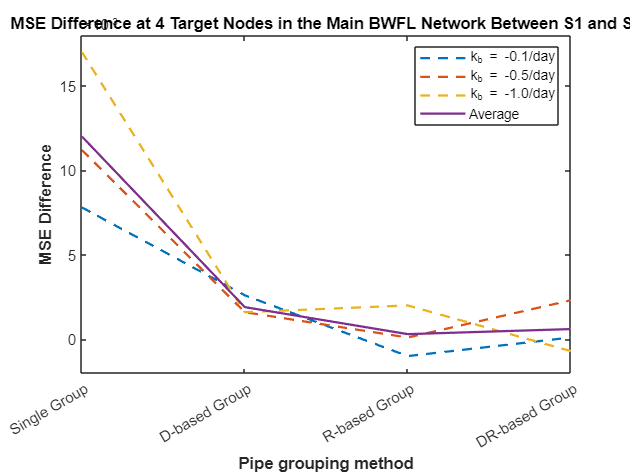

% Comparison between S1 and S2
S1 = [0.0206,0.0127,0.0087,0.0095;0.0240,0.0113,0.0093,0.0120;
    0.0280,0.0121,0.0112,0.0094;0.0242,0.0120,0.0097,0.0103];
S2 = [0.0128,0.0101,0.0097,0.0094;0.0128,0.0097,0.0092,0.0097;
    0.0110,0.0105,0.0092,0.0101;0.0122,0.0101,0.0094,0.0097];
S_diff = S1 - S2;

figure,
for i = 1:3
    plot(1:4,S_diff(i,:),"LineWidth",1.5,"LineStyle","--");
    hold on
end
plot(1:4,S_diff(4,:),"LineWidth",1.5);
legend({'k_b = -0.1/day','k_b = -0.5/day','k_b = -1.0/day','Average'})
xlabel('Pipe grouping method',FontWeight='bold')
ylabel('MSE Difference',FontWeight='bold')
title('MSE Difference at 4 Target Nodes in the Main BWFL Network Between S1 and S2');
xticks(1:4)
xticklabels({'Single Group','D-based Group','R-based Group','DR-based Group'})

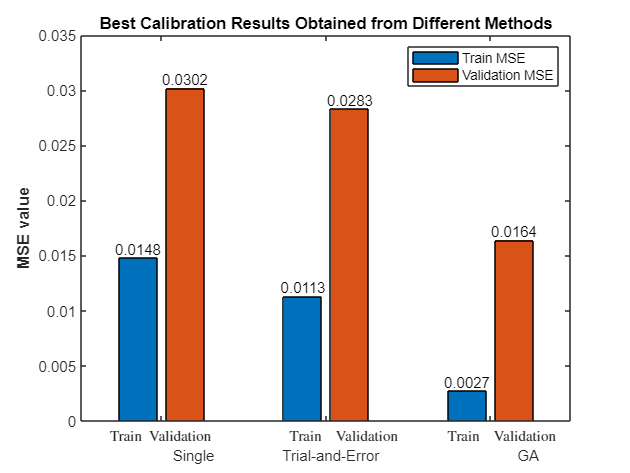

% Comparison between best GA, manual and initial single bulk decay
GA_best = [0.0027, 0.0164];
Trial_best = [0.0113, 0.0283];
Original_best = [0.0148, 0.0302];

b = bar([Original_best; Trial_best; GA_best]);
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(b(2).YData);
text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

xticklabels({'Train Validation\newline         Single','     Train  Validation\newline    Trial-and-Error', ...
    '   Train  Validation\newline             GA'})
ylabel('MSE value','FontWeight','bold')
title('Best Calibration Results Obtained from Different Methods')
legend('Train MSE','Validation MSE');